## 数据管理

clear;
% data=load('Algorithm_B\GRU_PA1.mat');
% GRU = data.model;
% save('Algorithm_B\Alg_PA1.mat',"GRU",'-mat');

% data=load('Algorithm_B\Alg_PD.mat');
% GRU=data.GRU;
% Simple_FCN=data.Simple_FCN;
% FNN=data.FNN;
% save('Algorithm_B\Alg_PD.mat','GRU','Simple_FCN','FNN','-mat');



## 数据转换

% clear;
% data=load('ModB4_39dB\Alg_PD.mat');
% model=data.FNN;
% save('ModB4_39dB\FNN_PD.mat','model','-mat');
% 
% data=load('ModB4_39dB\Alg_PA1.mat');
% model=data.FNN;
% save('ModB4_39dB\FNN_PA1.mat','model','-mat');
% 
% data=load('ModB4_39dB\Alg_PA3.mat');
% model=data.FNN;
% save('ModB4_39dB\FNN_PA3.mat','model','-mat');
% 
% data=load('ModB4_39dB\Alg_PA2.mat');
% model=data.FNN;
% save('ModB4_39dB\FNN_PA2.mat','model','-mat');
% 
% data=load('ModB4_39dB\Alg_PA4.mat');
% model=data.FNN;
% save('ModB4_39dB\FNN_PA4.mat','model','-mat');


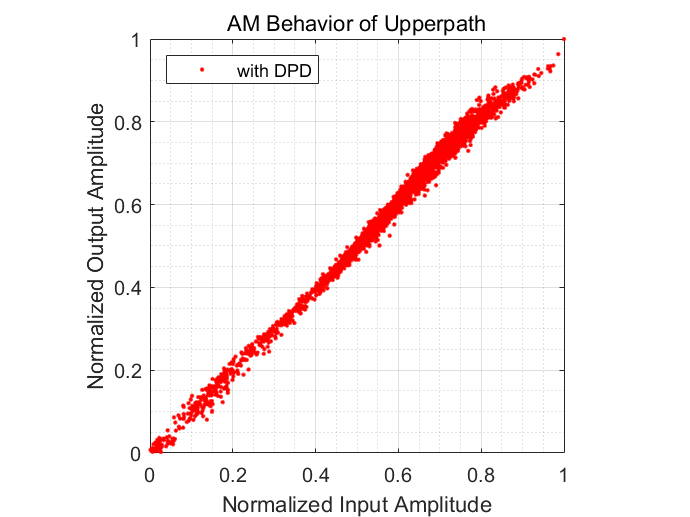

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);

% 参数需要保持一致
M=7;
Sys_input_DPD=DPD_store(Sys_input,M,9,'Output\GRU_PD.mat');
[S_U1,S_D1]=Power_Divider(Sys_input_DPD);
S_U1_DPD= DPD_store(S_U1,M,9,'Output\GRU_PA1.mat');
S_U2    = PA_1(S_U1_DPD);
S_U2_DPD= DPD_store(S_U2,M,9,'Output\GRU_PA3.mat');
S_U3    = PA_3(S_U2_DPD);
S_D1_DPD= DPD_store(S_D1,M,9,'Output\GRU_PA2.mat');
S_D2    = PA_2(S_D1_DPD);
S_D2_DPD= DPD_store(S_D2,M,9,'Output\GRU_PA4.mat');
S_D3    = PA_4(S_D2_DPD);
Sys_output_sim=Power_Combiner(S_U3,S_D3);

% 性能评估
% err=abs(Sys_output_sim-Sys_output) %模型本身的误差
Plot_AM(S_U1,S_U3,'AM Behavior of Upperpath','with DPD');

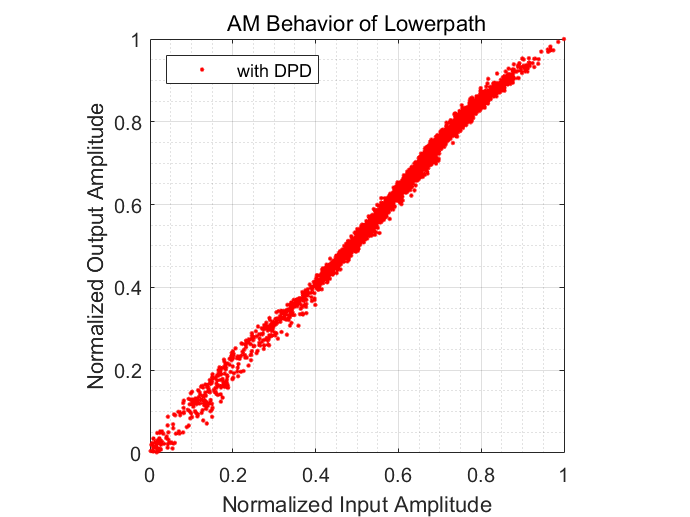

Plot_AM(S_D1,S_D3,'AM Behavior of Lowerpath','with DPD');

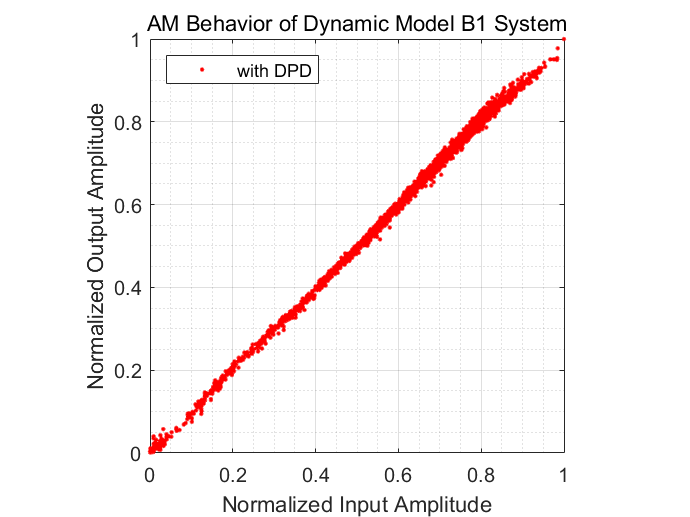

Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Dynamic Model B1 System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model B3，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model B3，系统的NMSE仿真结果为 -34.753870 dB
